# Download and Explore the Input Image Sequence

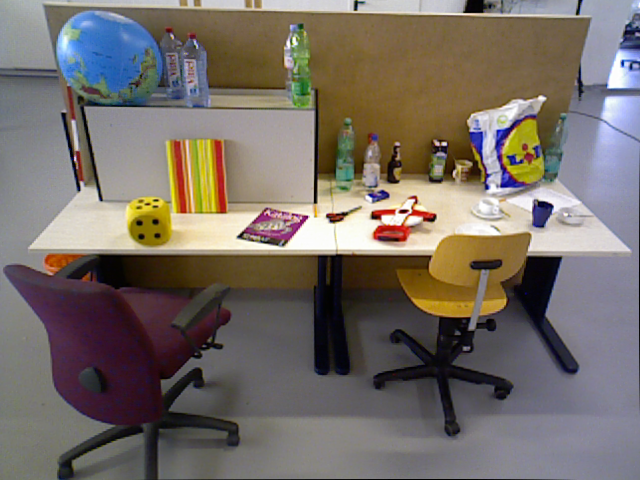

% Create an imageDatastore object to inspect the RGB images.
imageFolder   = 'C:\Users\vivek\OneDrive - Arizona State University\documents\MS\Semester 2\Perception\Project\rgbd_dataset_freiburg3_long_office_household\rgb';
imds          = imageDatastore(imageFolder);

% Inspect the first image
currFrameIdx = 1;
currI = readimage(imds, currFrameIdx);
himage = imshow(currI);

## MAP INITIALIZATION

% Set random seed for reproducibility
rng(0);

% Create a cameraIntrinsics object to store the camera intrinsic parameters.
% The intrinsics for the dataset can be found at the following page:
% https://vision.in.tum.de/data/datasets/rgbd-dataset/file_formats
% Note that the images in the dataset are already undistorted, hence there
% is no need to specify the distortion coefficients.
focalLength    = [535.4, 539.2];    % in units of pixels
principalPoint = [320.1, 247.6];    % in units of pixels
imageSize      = size(currI,[1 2]);  % in units of pixels
intrinsics     = cameraIntrinsics(focalLength, principalPoint, imageSize);

% Detect and extract ORB features
scaleFactor = 1.2;
numLevels   = 8;
numPoints   = 1000;
[preFeatures, prePoints] = helperDetectAndExtractFeatures(currI, scaleFactor, numLevels, numPoints);

currFrameIdx = currFrameIdx + 1;
firstI       = currI; % Preserve the first frame

isMapInitialized  = false;

% Map initialization loop
while ~isMapInitialized && currFrameIdx < numel(imds.Files)
    currI = readimage(imds, currFrameIdx);
    
    [currFeatures, currPoints] = helperDetectAndExtractFeatures(currI, scaleFactor, numLevels, numPoints);
    
    currFrameIdx = currFrameIdx + 1;
    
    % Find putative feature matches
    indexPairs = matchFeatures(preFeatures, currFeatures, 'Unique', true, ...
        'MaxRatio', 0.9, 'MatchThreshold', 40);
    
    % If not enough matches are found, check the next frame
    minMatches = 100;
    if size(indexPairs, 1) < minMatches
        continue
    end
    
    preMatchedPoints  = prePoints(indexPairs(:,1),:);
    currMatchedPoints = currPoints(indexPairs(:,2),:);
    
    % Compute homography and evaluate reconstruction
    [tformH, scoreH, inliersIdxH] = helperComputeHomography(preMatchedPoints, currMatchedPoints);
    
    % Compute fundamental matrix and evaluate reconstruction
    [tformF, scoreF, inliersIdxF] = helperComputeFundamentalMatrix(preMatchedPoints, currMatchedPoints);
    
    % Select the model based on a heuristic
    ratio = scoreH/(scoreH + scoreF);
    ratioThreshold = 0.45;
    if ratio > ratioThreshold
        inlierTformIdx = inliersIdxH;
        tform          = tformH;
    else
        inlierTformIdx = inliersIdxF;
        tform          = tformF;
    end
    
    % Computes the camera location up to scale. Use half of the
    % points to reduce computation
    inlierPrePoints  = preMatchedPoints(inlierTformIdx,:);
    inlierCurrPoints = currMatchedPoints(inlierTformIdx,:);
    [relPose, validFraction] = estrelpose(tform, intrinsics, ...
        inlierPrePoints(1:2:end), inlierCurrPoints(1:2:end));
    
    % If not enough inliers are found, move to the next frame
    if validFraction < 0.9 || numel(relPose)>1
        continue
    end
    
    % Triangulate two views to obtain 3-D map points
    minParallax = 1; % In degrees
    [isValid, xyzWorldPoints, inlierTriangulationIdx] = helperTriangulateTwoFrames(...
        rigidtform3d, relPose, inlierPrePoints, inlierCurrPoints, intrinsics, minParallax);
    
    if ~isValid
        continue
    end
    
    % Get the original index of features in the two key frames
    indexPairs = indexPairs(inlierTformIdx(inlierTriangulationIdx),:);
    
    isMapInitialized = true;
    
    disp(['Map initialized with frame 1 and frame ', num2str(currFrameIdx-1)])
end % End of map initialization loop

Map initialized with frame 1 and frame 26


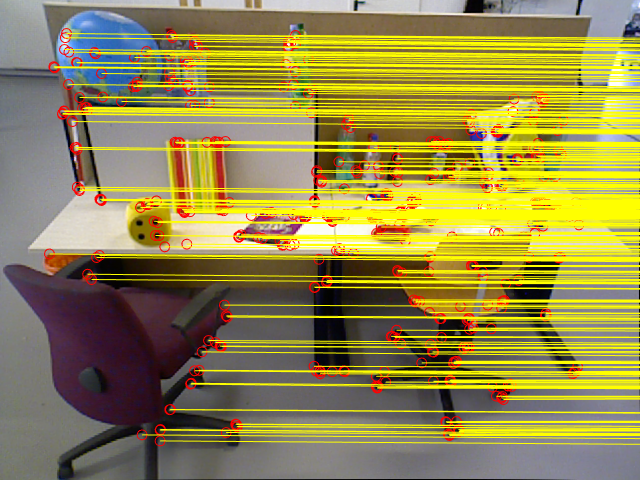

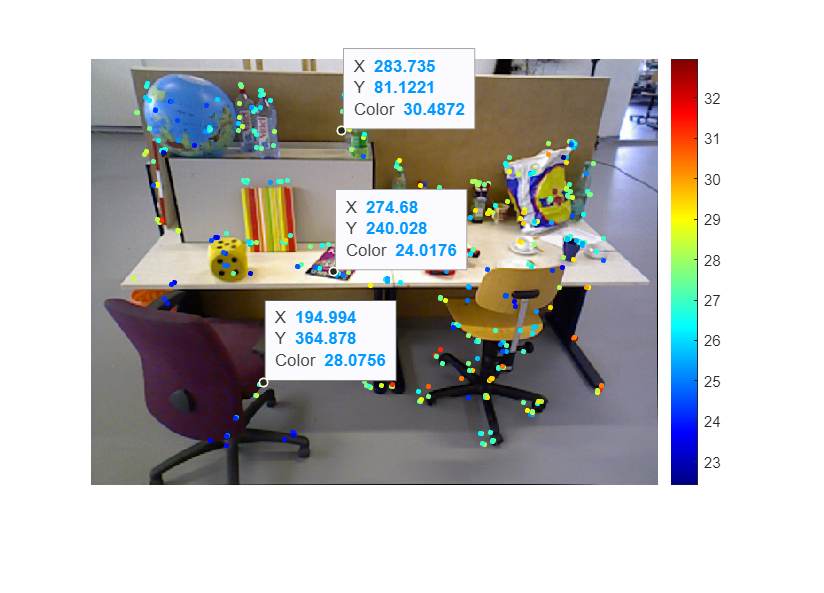


if isMapInitialized
    % Show matched features
    hfeature = showMatchedFeatures(firstI, currI, prePoints(indexPairs(:,1)), ...
        currPoints(indexPairs(:, 2)), "Montage");
    
    % Assuming depthValues is available (depth values corresponding to each pixel)
    % Convert 3D world points to image coordinates
    imagePoints = worldToImage(intrinsics, relPose, xyzWorldPoints);
    
    % Plot the image
    figure;
    imshow(currI);
    hold on;

    % Plot the 3D points as circles with depth-based colors
    depthValues = xyzWorldPoints(:, 3);
    colormap('jet'); % Choose a colormap
    scatter(imagePoints(:, 1), imagePoints(:, 2), 10, depthValues, 'filled');
    colorbar;  % Add a colorbar to show the mapping between depth value and color

    hold off;

ax = gca;
chart = ax.Children(1);
datatip(chart,287.3,79.38);
datatip(chart,278.9,235.2);
datatip(chart,193.5,362.5);


else
    error('Unable to initialize the map.')
end

## Store Initial Key Frames and Map Points

% Create an empty imageviewset object to store key frames
vSetKeyFrames = imageviewset;

% Create an empty worldpointset object to store 3-D map points
mapPointSet   = worldpointset;

% Add the first key frame. Place the camera associated with the first
% key frame at the origin, oriented along the Z-axis
preViewId     = 1;
vSetKeyFrames = addView(vSetKeyFrames, preViewId, rigidtform3d, Points=prePoints,...
    Features=preFeatures.Features);

% Add the second key frame
currViewId    = 2;
vSetKeyFrames = addView(vSetKeyFrames, currViewId, relPose, Points=currPoints,...
    Features=currFeatures.Features);

% Add connection between the first and the second key frame
vSetKeyFrames = addConnection(vSetKeyFrames, preViewId, currViewId, relPose, Matches=indexPairs);

% Add 3-D map points
[mapPointSet, newPointIdx] = addWorldPoints(mapPointSet, xyzWorldPoints);

% Add observations of the map points
preLocations  = prePoints.Location;
currLocations = currPoints.Location;
preScales     = prePoints.Scale;
currScales    = currPoints.Scale;

% Add image points corresponding to the map points in the first key frame
mapPointSet   = addCorrespondences(mapPointSet, preViewId, newPointIdx, indexPairs(:,1));

% Add image points corresponding to the map points in the second key frame
mapPointSet   = addCorrespondences(mapPointSet, currViewId, newPointIdx, indexPairs(:,2));

## Initialize Place Recognition Database

% Load the bag of features data created offline
bofData         = load("bagOfFeaturesDataSLAM.mat");

% Initialize the place recognition database
loopDatabase    = invertedImageIndex(bofData.bof,SaveFeatureLocations=false);

% Add features of the first two key frames to the database
addImageFeatures(loopDatabase, preFeatures, preViewId);
addImageFeatures(loopDatabase, currFeatures, currViewId);

## Refine and Visualize the Initial Reconstruction

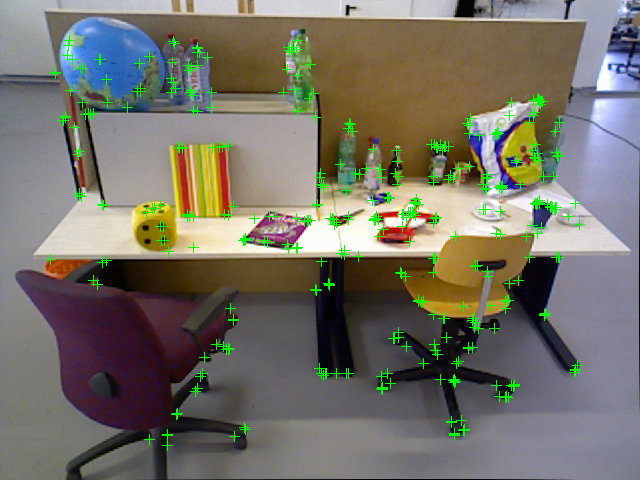

% Run full bundle adjustment on the first two key frames
tracks       = findTracks(vSetKeyFrames);
cameraPoses  = poses(vSetKeyFrames);

[refinedPoints, refinedAbsPoses] = bundleAdjustment(xyzWorldPoints, tracks, ...
    cameraPoses, intrinsics, FixedViewIDs=1, ...
    PointsUndistorted=true, AbsoluteTolerance=1e-7,...
    RelativeTolerance=1e-15, MaxIteration=20, ...
    Solver="preconditioned-conjugate-gradient");

% Scale the map and the camera pose using the median depth of map points
medianDepth   = median(vecnorm(refinedPoints.'));
refinedPoints = refinedPoints / medianDepth;

refinedAbsPoses.AbsolutePose(currViewId).Translation = ...
    refinedAbsPoses.AbsolutePose(currViewId).Translation / medianDepth;
relPose.Translation = relPose.Translation/medianDepth;

% Update key frames with the refined poses
vSetKeyFrames = updateView(vSetKeyFrames, refinedAbsPoses);
vSetKeyFrames = updateConnection(vSetKeyFrames, preViewId, currViewId, relPose);

% Update map points with the refined positions
mapPointSet = updateWorldPoints(mapPointSet, newPointIdx, refinedPoints);

% Update view direction and depth
mapPointSet = updateLimitsAndDirection(mapPointSet, newPointIdx, vSetKeyFrames.Views);

% Update representative view
mapPointSet = updateRepresentativeView(mapPointSet, newPointIdx, vSetKeyFrames.Views);

% Visualize matched features in the current frame
close(hfeature.Parent.Parent);
featurePlot = helperVisualizeMatchedFeatures(currI, currPoints(indexPairs(:,2)));

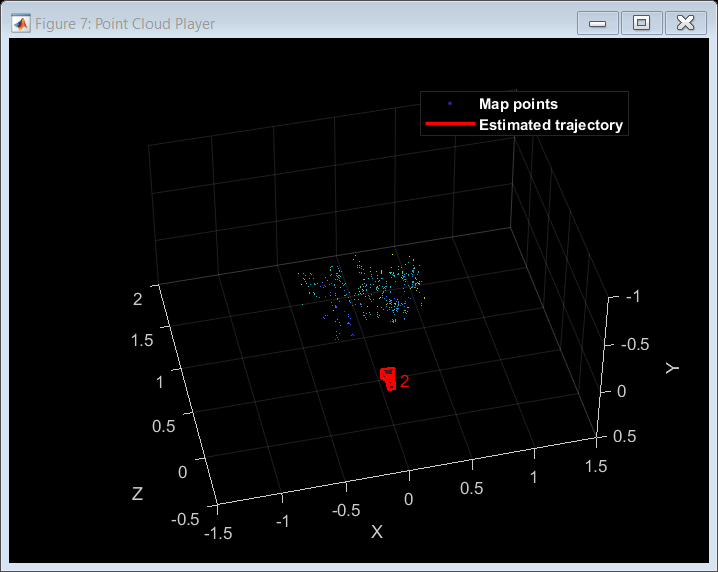


% Visualize initial map points and camera trajectory
mapPlot = helperVisualizeMotionAndStructure(vSetKeyFrames, mapPointSet);

% Show legend
showLegend(mapPlot);

## Tracking

% ViewId of the current key frame
currKeyFrameId   = currViewId;

% ViewId of the last key frame
lastKeyFrameId   = currViewId;

% Index of the last key frame in the input image sequence
lastKeyFrameIdx  = currFrameIdx - 1;

% Indices of all the key frames in the input image sequence
addedFramesIdx   = [1; lastKeyFrameIdx];

isLoopClosed     = false;

## MAIN LOOP

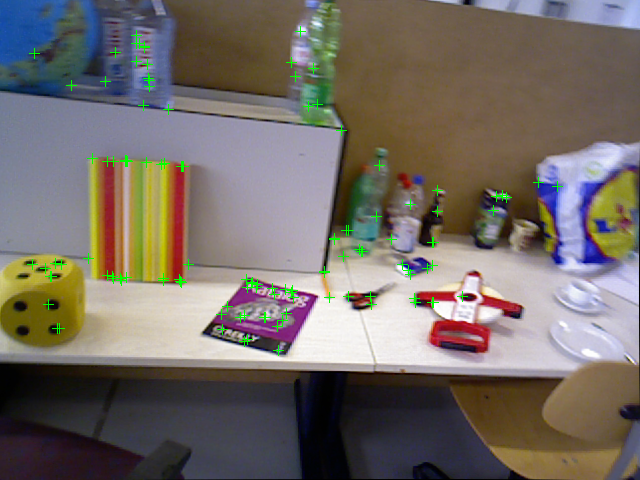

% Main loop
isLastFrameKeyFrame = true;
while ~isLoopClosed && currFrameIdx < numel(imds.Files)
    currI = readimage(imds, currFrameIdx);
    
    [currFeatures, currPoints] = helperDetectAndExtractFeatures(currI, scaleFactor, numLevels, numPoints);
    
    % Track the last key frame
    % mapPointsIdx:   Indices of the map points observed in the current frame
    % featureIdx:     Indices of the corresponding feature points in the
    %                 current frame
    [currPose, mapPointsIdx, featureIdx] = helperTrackLastKeyFrame(mapPointSet, ...
        vSetKeyFrames.Views, currFeatures, currPoints, lastKeyFrameId, intrinsics, scaleFactor);
    
    % Track the local map and check if the current frame is a key frame.
    % A frame is a key frame if both of the following conditions are satisfied:
    %
    % 1. At least 20 frames have passed since the last key frame or the
    %    current frame tracks fewer than 100 map points.
    % 2. The map points tracked by the current frame are fewer than 90% of
    %    points tracked by the reference key frame.
    %
    % Tracking performance is sensitive to the value of numPointsKeyFrame.
    % If tracking is lost, try a larger value.
    %
    % localKeyFrameIds:   ViewId of the connected key frames of the current frame
    numSkipFrames     = 20;
    numPointsKeyFrame = 90;
    [localKeyFrameIds, currPose, mapPointsIdx, featureIdx, isKeyFrame] = ...
        helperTrackLocalMap(mapPointSet, vSetKeyFrames, mapPointsIdx, ...
        featureIdx, currPose, currFeatures, currPoints, intrinsics, scaleFactor, numLevels, ...
        isLastFrameKeyFrame, lastKeyFrameIdx, currFrameIdx, numSkipFrames, numPointsKeyFrame);
    
    % Visualize matched features
    updatePlot(featurePlot, currI, currPoints(featureIdx));

    
    if ~isKeyFrame
        currFrameIdx        = currFrameIdx + 1;
        isLastFrameKeyFrame = false;
        continue
    else
        isLastFrameKeyFrame = true;
    end

    % Update current key frame ID
    currKeyFrameId  = currKeyFrameId + 1;


## LOCAL MAPPING

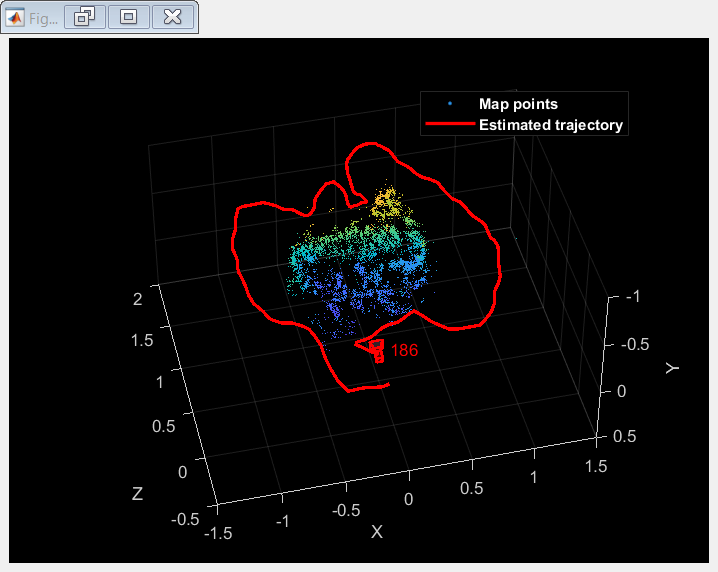

    % Add the new key frame
    [mapPointSet, vSetKeyFrames] = helperAddNewKeyFrame(mapPointSet, vSetKeyFrames, ...
        currPose, currFeatures, currPoints, mapPointsIdx, featureIdx, localKeyFrameIds);
    
    % Remove outlier map points that are observed in fewer than 3 key frames
    outlierIdx    = setdiff(newPointIdx, mapPointsIdx);
    if ~isempty(outlierIdx)
        mapPointSet   = removeWorldPoints(mapPointSet, outlierIdx);
    end
    
    % Create new map points by triangulation
    minNumMatches = 10;
    minParallax   = 3;
    [mapPointSet, vSetKeyFrames, newPointIdx] = helperCreateNewMapPoints(mapPointSet, vSetKeyFrames, ...
        currKeyFrameId, intrinsics, scaleFactor, minNumMatches, minParallax);
    
    % Local bundle adjustment
    [refinedViews, dist] = connectedViews(vSetKeyFrames, currKeyFrameId, MaxDistance=2);
    refinedKeyFrameIds = refinedViews.ViewId;
    fixedViewIds = refinedKeyFrameIds(dist==2);
    fixedViewIds = fixedViewIds(1:min(10, numel(fixedViewIds)));
    
    % Refine local key frames and map points
    [mapPointSet, vSetKeyFrames, mapPointIdx] = bundleAdjustment(...
        mapPointSet, vSetKeyFrames, [refinedKeyFrameIds; currKeyFrameId], intrinsics, ...
        FixedViewIDs=fixedViewIds, PointsUndistorted=true, AbsoluteTolerance=1e-7,...
        RelativeTolerance=1e-16, Solver="preconditioned-conjugate-gradient", ...
        MaxIteration=10);
    
    % Update view direction and depth
    mapPointSet = updateLimitsAndDirection(mapPointSet, mapPointIdx, vSetKeyFrames.Views);
    
    % Update representative view
    mapPointSet = updateRepresentativeView(mapPointSet, mapPointIdx, vSetKeyFrames.Views);
    
    % Visualize 3D world points and camera trajectory
    updatePlot(mapPlot, vSetKeyFrames, mapPointSet);

## LOOP CLOSURE

    % Check loop closure after some key frames have been created
    if currKeyFrameId > 20
        
        % Minimum number of feature matches of loop edges
        loopEdgeNumMatches = 50;
        
        % Detect possible loop closure key frame candidates
        [isDetected, validLoopCandidates] = helperCheckLoopClosure(vSetKeyFrames, currKeyFrameId, ...
            loopDatabase, currI, loopEdgeNumMatches);
        
        if isDetected
            % Add loop closure connections
            [isLoopClosed, mapPointSet, vSetKeyFrames] = helperAddLoopConnections(...
                mapPointSet, vSetKeyFrames, validLoopCandidates, currKeyFrameId, ...
                currFeatures, loopEdgeNumMatches);
        end
    end

Loop edge added between keyframe: 2 and 186


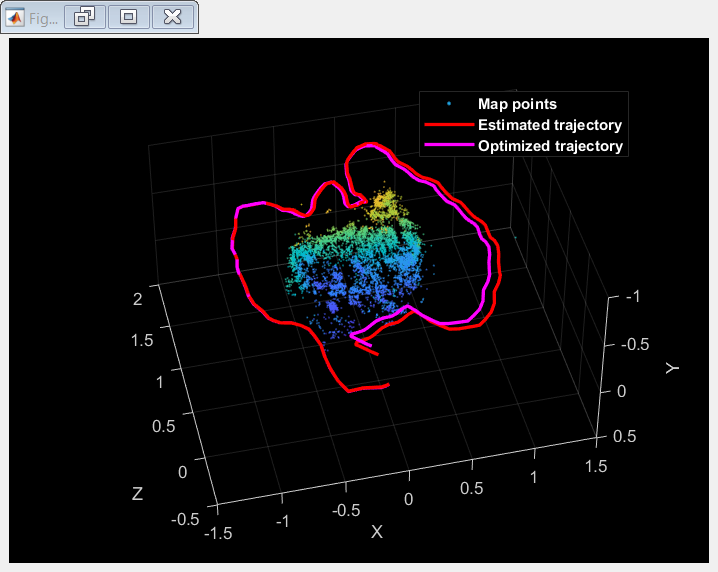

    
    % If no loop closure is detected, add current features into the database
    if ~isLoopClosed
        addImageFeatures(loopDatabase,  currFeatures, currKeyFrameId);
    end
    
    % Update IDs and indices
    lastKeyFrameId  = currKeyFrameId;
    lastKeyFrameIdx = currFrameIdx;
    addedFramesIdx  = [addedFramesIdx; currFrameIdx]; 
    currFrameIdx    = currFrameIdx + 1;
end
% End of main loop

if isLoopClosed
    % Optimize the poses
    minNumMatches      = 20;
    vSetKeyFramesOptim = optimizePoses(vSetKeyFrames, minNumMatches, Tolerance=1e-16);
    
    % Update map points after optimizing the poses
    mapPointSet = helperUpdateGlobalMap(mapPointSet, vSetKeyFrames, vSetKeyFramesOptim);
    
    updatePlot(mapPlot, vSetKeyFrames, mapPointSet);
    
    % Plot the optimized camera trajectory
    optimizedPoses  = poses(vSetKeyFramesOptim);
    plotOptimizedTrajectory(mapPlot, optimizedPoses)
    
    % Update legend
    showLegend(mapPlot);
end

## Compare with the Ground Truth

% Load ground truth
gTruthData = load("orbslamGroundTruth.mat");
gTruth     = gTruthData.gTruth;

% Plot the actual camera trajectory
plotActualTrajectory(mapPlot, gTruth(addedFramesIdx), optimizePoses);

Unrecognized function or variable 'optimizePoses'.


% Show legend
showLegend(mapPlot);

## ACCURACY

rmse = helperEstimateTrajectoryError(gTruth(addedFramesIdx), optimizedPoses);
accuracy = (1 - rmse)*100;
disp(['Absolute RMSE for key frame trajectory (m): ', num2str(accuracy),'%']);